## HCP Main Sample - Whole-Brain Coupling Plot Across Coupling Measures

Computation of coupling measure-specific brain-average coupling values for all eight conditions, taking the mean across the eight condition-specific coupling values per coupling measure and creating the violin plot visualizing coupling measure-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average measure-specific SC-FC coupling. 

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:532
    whole_brain_values_HCP_rest{i,1} = mean(final_r_all_HCP_rest_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_rest{i,2} = mean(final_r_all_HCP_rest_532{i,1}(:,2));% G 
    whole_brain_values_HCP_rest{i,3} = mean(final_r_all_HCP_rest_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_rest{i,4} = mean(final_r_all_HCP_rest_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_rest_table = cell2table(whole_brain_values_HCP_rest);
 whole_brain_values_HCP_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_rest_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.26241    0.26921    0.28842    0.20958
    0.26472    0.27125    0.28796    0.16062
    0.28671    0.29102     0.3157     0.2594
    0.25345    0.25433    0.27388    0.22293
    0.30403    0.29867    0.32095    0.25023
    0.30824    0.32697    0.34864    0.30061
    0.29297     0.2847    0.30774     0.2275
     0.2587    0.27543     0.2901    0.22258
    0.28783    0.28327    0.30911    0.26172
    0.28416    0.29294    0.30979    0.21278
    0.29607     0.3054    0.32864    0.23963
     0.3242    0.32659    0.35901    0.28468
    0.28998    0.28396     0.3105    0.22044
    0.26265    0.28207    0.29989    0.21407
    0.28991    0.29946     0.3166    0.23476
    0.25791     0.2755    0.29123     0.2126


1.2. Emotion processing (176 frames)

for i = 1:532
    whole_brain_values_HCP_emotion{i,1} = mean(final_r_all_HCP_emotion_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_emotion{i,2} = mean(final_r_all_HCP_emotion_532{i,1}(:,2));% G 
    whole_brain_values_HCP_emotion{i,3} = mean(final_r_all_HCP_emotion_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_emotion{i,4} = mean(final_r_all_HCP_emotion_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_emotion_table = cell2table(whole_brain_values_HCP_emotion);
 whole_brain_values_HCP_emotion_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_emotion_table = 532×4 table
      Pl          G         Cos         SI   
    _______    _______    _______    ________

    0.15874    0.18069    0.18416      0.1281
    0.17971    0.18118    0.19089     0.13498
    0.16282    0.16631    0.16981     0.13584
    0.11691    0.12941    0.12784    0.092762
    0.18926    0.17597    0.18696     0.15995
    0.15549    0.16715    0.17083      0.1412
    0.15393    0.15751    0.15502     0.11522
    0.20942     0.2074    0.22418     0.19199
    0.13149    0.13353    0.13596     0.10859
     0.1549    0.16317    0.16582     0.12122
     0.1729    0.18002    0.18078     0.14643
    0.18051    0.18957    0.19886     0.15811
    0.16788    0.18257    0.18569     0.12053
    0.13297    0.15542    0.14547    0.091491
    0.16904    0.17487    0.17824     0.12873
    0.18934     0.1876    0.20

1.3. Gambling (253 frames)

for i = 1:532
    whole_brain_values_HCP_gambling{i,1} = mean(final_r_all_HCP_gambling_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_gambling{i,2} = mean(final_r_all_HCP_gambling_532{i,1}(:,2));% G 
    whole_brain_values_HCP_gambling{i,3} = mean(final_r_all_HCP_gambling_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_gambling{i,4} = mean(final_r_all_HCP_gambling_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_gambling_table = cell2table(whole_brain_values_HCP_gambling);
 whole_brain_values_HCP_gambling_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_gambling_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19335    0.21377     0.2155    0.16249
    0.19885    0.20184    0.20869     0.1222
    0.21984    0.22077    0.22975    0.20427
    0.16632    0.18043    0.17986     0.1341
    0.23102    0.23672    0.24824    0.19149
    0.20468    0.21825     0.2221    0.18572
    0.21935    0.21034    0.21649    0.17667
    0.20181    0.21335      0.219    0.17721
    0.20394    0.20226     0.2133    0.17234
    0.19121    0.20003    0.20073    0.14938
    0.23787     0.2419    0.25002    0.20178
    0.24564    0.25902    0.27315     0.2026
    0.20317    0.21969    0.21809    0.14788
    0.21812    0.23659    0.23759    0.17423
     0.2333    0.24052    0.24947    0.18886
    0.22348    0.23465     0.2428     0.1861


1.4. Language (316 frames)

for i = 1:532
    whole_brain_values_HCP_language{i,1} = mean(final_r_all_HCP_language_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_language{i,2} = mean(final_r_all_HCP_language_532{i,1}(:,2));% G 
    whole_brain_values_HCP_language{i,3} = mean(final_r_all_HCP_language_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_language{i,4} = mean(final_r_all_HCP_language_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_language_table = cell2table(whole_brain_values_HCP_language);
 whole_brain_values_HCP_language_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_language_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.23125    0.24837    0.25979    0.19057
    0.26861    0.27301    0.28915    0.18894
    0.24599    0.25279    0.26061    0.21081
    0.20501    0.22562    0.23267    0.15728
    0.24057    0.24402    0.25761    0.18531
    0.26923    0.27437    0.28811    0.23758
    0.22293    0.22587    0.23326    0.15435
    0.24359    0.24789    0.26384    0.19607
    0.27781    0.26875     0.2932    0.23541
    0.25931    0.25899    0.27663    0.20737
    0.24011    0.26717    0.26707    0.16977
    0.24529    0.26123    0.27648    0.20221
    0.22784    0.25427    0.25482    0.14288
    0.24406    0.26842    0.27258    0.17955
    0.22385    0.24398      0.243    0.15912
     0.2733    0.26705     0.2875    0.22969


1.5. Motor (284 frames)

for i = 1:532
    whole_brain_values_HCP_motor{i,1} = mean(final_r_all_HCP_motor_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_motor{i,2} = mean(final_r_all_HCP_motor_532{i,1}(:,2));% G 
    whole_brain_values_HCP_motor{i,3} = mean(final_r_all_HCP_motor_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_motor{i,4} = mean(final_r_all_HCP_motor_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_motor_table = cell2table(whole_brain_values_HCP_motor);
 whole_brain_values_HCP_motor_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_motor_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.21296    0.21882    0.23168       0.16
    0.21753     0.2216    0.22654    0.14892
    0.21657    0.21377    0.21798     0.1834
    0.18294    0.19344    0.19497    0.15645
    0.21586    0.20767    0.21016    0.16856
    0.21604    0.22845    0.23214    0.18362
     0.1917    0.18832    0.19951     0.1581
    0.19371    0.20696    0.21247    0.16014
    0.18691      0.189    0.19956    0.15669
    0.18443    0.19468    0.19856    0.14163
    0.21703    0.22455     0.2291    0.16899
    0.23763    0.23915    0.25339    0.19668
    0.19346    0.19961    0.19984    0.12872
    0.21464     0.2226    0.22996    0.17338
    0.19314    0.20186    0.20472    0.15257
    0.21632    0.22207    0.22967    0.19032


1.6. Relational (232 frames)

for i = 1:532
    whole_brain_values_HCP_relational{i,1} = mean(final_r_all_HCP_relational_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_relational{i,2} = mean(final_r_all_HCP_relational_532{i,1}(:,2));% G 
    whole_brain_values_HCP_relational{i,3} = mean(final_r_all_HCP_relational_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_relational{i,4} = mean(final_r_all_HCP_relational_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_relational_table = cell2table(whole_brain_values_HCP_relational);
 whole_brain_values_HCP_relational_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_relational_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.20417    0.23185    0.23351    0.15225
    0.21111    0.22374    0.23086     0.1362
    0.22722    0.22828    0.23872    0.20823
    0.17735    0.18916    0.18851    0.14109
    0.18823    0.19213      0.195    0.15866
    0.20219    0.21948     0.2272    0.17958
     0.2053    0.20659    0.21025    0.16441
    0.20991    0.21304    0.22834    0.19893
     0.2046    0.20425    0.21265    0.17393
    0.23025    0.24129    0.24708    0.18222
    0.22936    0.24234     0.2474     0.1935
    0.25399    0.25555    0.27489    0.20923
     0.1873    0.21297    0.21039    0.13197
    0.20203    0.21876    0.21981    0.16051
    0.23712    0.24758    0.26111    0.21001
    0.24761     0.2528     0.2654    0.19837

1.7. Social (274 frames)

for i = 1:532
    whole_brain_values_HCP_social{i,1} = mean(final_r_all_HCP_social_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_social{i,2} = mean(final_r_all_HCP_social_532{i,1}(:,2));% G 
    whole_brain_values_HCP_social{i,3} = mean(final_r_all_HCP_social_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_social{i,4} = mean(final_r_all_HCP_social_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_social_table = cell2table(whole_brain_values_HCP_social);
 whole_brain_values_HCP_social_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_social_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.20427    0.23935     0.2436    0.16756
    0.22911    0.24716    0.25299    0.15463
    0.21756    0.23493    0.23864    0.18277
    0.18347    0.20058     0.2031    0.15604
    0.23466     0.2426    0.26051    0.21153
    0.21337    0.23565    0.23704    0.18782
    0.17826    0.20319    0.20068    0.11304
    0.23371    0.23908    0.25272    0.20974
    0.23085    0.23774    0.24789    0.18635
    0.19562    0.22312    0.22955    0.13954
    0.23788     0.2518    0.26197    0.20178
    0.23186    0.25789    0.27445    0.21211
    0.22611    0.24868    0.25637    0.17394
    0.18973    0.22637    0.21303    0.13303
    0.21325    0.24138    0.24552    0.17015
    0.23844    0.25218    0.26455    0.20931


1.8. WM (405 frames)

for i = 1:532
    whole_brain_values_HCP_wm{i,1} = mean(final_r_all_HCP_wm_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_wm{i,2} = mean(final_r_all_HCP_wm_532{i,1}(:,2));% G 
    whole_brain_values_HCP_wm{i,3} = mean(final_r_all_HCP_wm_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_wm{i,4} = mean(final_r_all_HCP_wm_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_wm_table = cell2table(whole_brain_values_HCP_wm);
 whole_brain_values_HCP_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_wm_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.22729    0.25821    0.25872    0.17912
    0.22539     0.2406    0.24439    0.16424
     0.2365     0.2491    0.25446    0.20201
    0.20176    0.22034    0.21169    0.17106
    0.25974    0.26576    0.27205    0.22287
    0.24268    0.26264     0.2698    0.23313
    0.23561    0.23575    0.23633    0.17257
    0.23709    0.25176    0.26438     0.2123
    0.21289    0.22301    0.22492     0.1792
    0.21779    0.22855     0.2306    0.17205
    0.26224     0.2709    0.28437    0.22876
    0.27817    0.28201    0.29996    0.23872
    0.22159    0.24562    0.23963     0.1533
    0.23234    0.26205    0.25844    0.18271
    0.27711    0.27188    0.28799     0.2357
    0.26027    0.26315    0.27527    0.21346


**2. Average the coupling measure-specific values across all conditions **

2.1. Take average across all PL values 

PL_values_from_all_conditions = [whole_brain_values_HCP_rest_table.Pl whole_brain_values_HCP_emotion_table.Pl whole_brain_values_HCP_gambling_table.Pl whole_brain_values_HCP_language_table.Pl whole_brain_values_HCP_motor_table.Pl whole_brain_values_HCP_relational_table.Pl whole_brain_values_HCP_social_table.Pl whole_brain_values_HCP_wm_table.Pl]
PL_all = mean(PL_values_from_all_conditions,2)

2.2. Take average across all G values 

G_values_from_all_conditions = [whole_brain_values_HCP_rest_table.G whole_brain_values_HCP_emotion_table.G whole_brain_values_HCP_gambling_table.G whole_brain_values_HCP_language_table.G whole_brain_values_HCP_motor_table.G whole_brain_values_HCP_relational_table.G whole_brain_values_HCP_social_table.G whole_brain_values_HCP_wm_table.G]
G_all = mean(G_values_from_all_conditions,2)

2.3. Take average across all CoS values 

CoS_values_from_all_conditions = [whole_brain_values_HCP_rest_table.Cos whole_brain_values_HCP_emotion_table.Cos whole_brain_values_HCP_gambling_table.Cos whole_brain_values_HCP_language_table.Cos whole_brain_values_HCP_motor_table.Cos whole_brain_values_HCP_relational_table.Cos whole_brain_values_HCP_social_table.Cos whole_brain_values_HCP_wm_table.Cos]
CoS_all = mean(CoS_values_from_all_conditions,2)

2.4. Take average across all SI values 

SI_values_from_all_conditions = [whole_brain_values_HCP_rest_table.SI whole_brain_values_HCP_emotion_table.SI whole_brain_values_HCP_gambling_table.SI whole_brain_values_HCP_language_table.SI whole_brain_values_HCP_motor_table.SI whole_brain_values_HCP_relational_table.SI whole_brain_values_HCP_social_table.SI whole_brain_values_HCP_wm_table.SI]
SI_all = mean(SI_values_from_all_conditions,2)

**3. Create the violin plot**

3.1. Put all values into one table 

Mean_values_coupling_measures = [PL_all G_all CoS_all SI_all]
% Mean_values_coupling_measures_cell = num2cell(Mean_values_coupling_measures)
% Mean_values_coupling_measures_table = cell2table(Mean_values_coupling_measures_cell)
% Mean_values_coupling_measures_table.Properties.VariableNames = {'PL', 'G', 'CoS', 'SI'}

3.2. Create violin plots

 violinplot(Mean_values_coupling_measures)
 ylabel('Brain-average Coupling (r)')
 xlabel('Coupling Measure')
 set(gca,'FontSize',15)
 ylim([0.05 0.4])

**4. Run ANOVA **

Mean_values_coupling_measures
groupnames = {'PL', 'G', 'CoS', 'SI'}

groupnames = 1×4 cell array
    {'PL'}    {'G'}    {'CoS'}    {'SI'}


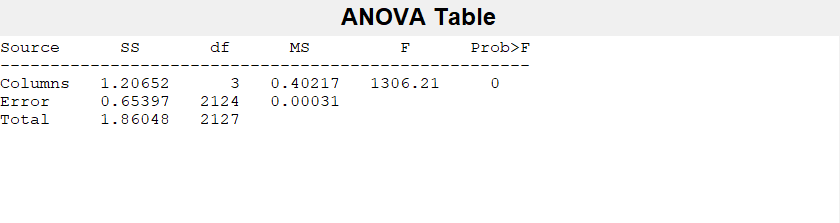

p = 0

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df'  }    {'MS'        }    {'F'         }    {'Prob>F'  }
    {'Columns'}    {[1.2065]}    {[   3]}    {[    0.4022]}    {[1.3062e+03]}    {[       0]}
    {'Error'  }    {[0.6540]}    {[2124]}    {[3.0789e-04]}    {0×0 double  }    {0×0 double}
    {'Total'  }    {[1.8605]}    {[2127]}    {0×0 double  }    {0×0 double  }    {0×0 double}


stats = struct with fields:
    gnames: [4×1 char]
         n: [532 532 532 532]
    source: 'anova1'
     means: [0.2281 0.2373 0.2475 0.1850]
        df: 2124
         s: 0.0175


[p,tbl,stats] = anova1(Mean_values_coupling_measures)

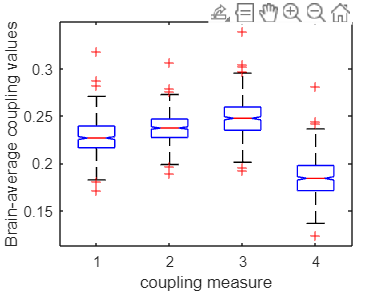

xlabel('coupling measure')
ylabel('Brain-average coupling values')

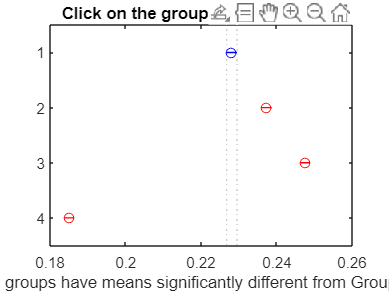

gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 6×6 table
    Group A    Group B    Lower Limit       A-B        Upper Limit     P-value  
    _______    _______    ___________    __________    ___________    __________

       1          2         -0.01195     -0.0091861    -0.0064222     3.4388e-17
       1          3        -0.022163      -0.019399     -0.016635              0
       1          4         0.040365       0.043129      0.045893              0
       2          3        -0.012977      -0.010213    -0.0074486     1.4754e-21
       2          4         0.049551       0.052315      0.055079              0
       3          4         0.059763       0.062527      0.065291              0
